**Discrete Optimal Path :**

This script shows how we can find the shortest path from a start goal to an end goal through a field of obstacles.

The first step is to setup out course load an obstacle course.  There are some already provided in ./obstacle_envs.

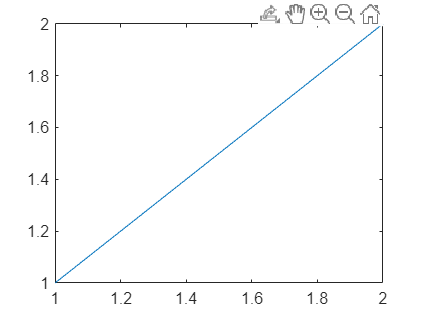

clearvars
global outputFcn_global_data x_vals obstacles 
plot([1 2],[1,2])

Solves optimal path through field of obstacles by solving the following minimization problem to find the shortest path from our start point to end point.


$$  \begin{array}{ccc}
    \underset{x}\text{min} & \sum_{i=1}^N\sqrt{(x_i-x_{i-1})^2 + (y_i-y_{i-1})^2} &  \\
    s.t. & (x_j - x_c)^2 + (y_j - y_c)^2 > R_c^2, &\forall j \in \{1,\ldots, N-1\} \\
  \end{array}$$
